
%#ok<*CLALL>

clear all;clc 

tspan = 1 : 1E-2 : 5; 
maxSpeed = 1E-1; 
initialStates = [-1; 0; 1; 0; maxSpeed; 0; 0; maxSpeed]; 

% State space system. 
A = [zeros(4) eye(4); zeros(4) zeros(4)]; 
B = [zeros(4); eye(4)]; 
% C = [eye(4) zeros(4)]; 
C = eye(8); 
D = 0; 
sys = ss(A, B, C, D); 

% Q matrix. 
Q = diag([1 1 -1 -1 0 0 0 0]); 

% R matrix. 
R = diag([1 1 -1 -1]); 

K = lqr(sys, Q, R)

K =     1.0000         0         0         0    1.4142         0         0         0
         0    1.0000         0         0         0    1.4142         0         0
         0         0    1.0000         0         0         0    1.4142         0
         0         0         0    1.0000         0         0         0    1.4142


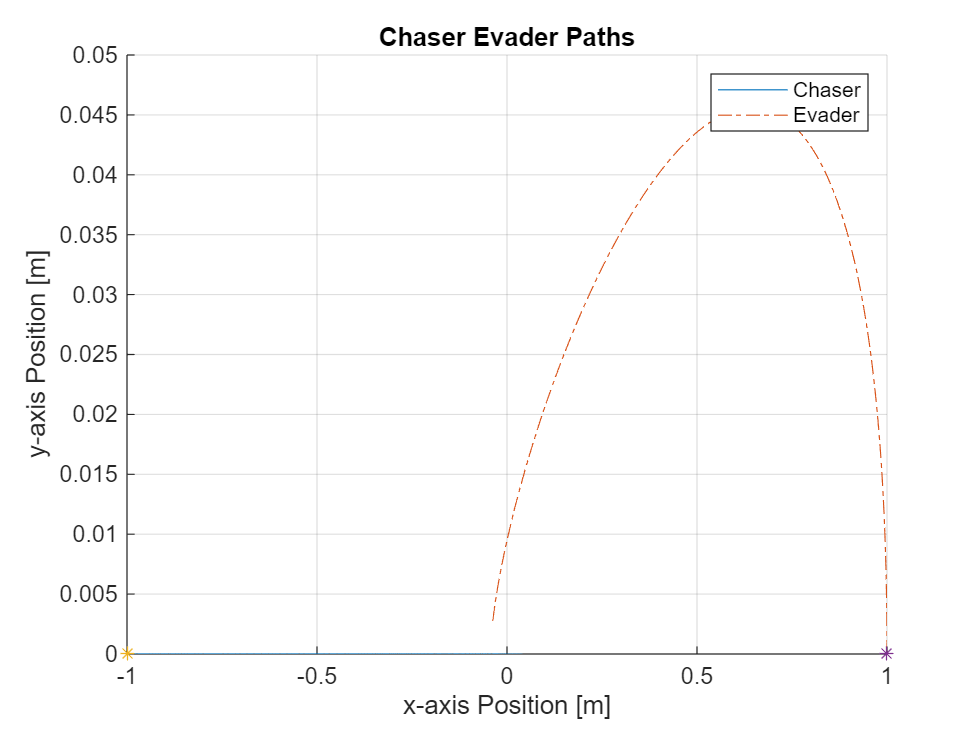

lqrSys = ss(A-B*K, B, C, D); 
y = (lsim(lqrSys, zeros(4, length(tspan)), tspan, initialStates)).'; 
chaserPath = y(1:2, :); 
evaderPath = y(3:4, :); 

clf; 
hold on; 
grid on; 
plot(chaserPath(1, :), chaserPath(2, :)); 
plot(evaderPath(1, :), evaderPath(2, :), "-."); 
plot(chaserPath(1, 1), chaserPath(2, 1), "*"); 
plot(evaderPath(1, 1), evaderPath(2, 1), "*"); 
title("Chaser Evader Paths"); 
xlabel("x-axis Position [m]"); 
ylabel("y-axis Position [m]"); 
legend("Chaser", "Evader"); 
% axis([-2 1 -1 1.6]); 
hold off;  